# Análise de sistemas dinâmicos

## Boas práticas

clear all;                  % limpa as variáveis
clc;                        % limpa a tela
close all;                  % fecha as figuras abertas




## Definir a função de transferência

Np = [2979];
Dp = [1 28 0];

Gp = tf(Np,Dp)

Gp =
 
     2979
  ----------
  s^2 + 28 s
 
Continuous-time transfer function.



Temos o ganho em malha fechada:


$$G_{MF}(s) = \frac{G_{ma}(s)}{1+G_{ma}(s)}$$


Como ajustar o ganho de malha de aberta (Eq1):


$$G_{MF}(s) = \frac{KG_c(s)G_p(s)}{1+KG_c(s)G_p(s)}$$


- Dificilmenet eu modifico o ganho da planta - Gp(s) "fixo".

- Ajusto o ganho de malha fechada modificando Gc(s).

- Modifico a posição dos polos de malha fechada modificando o ganho K.


% admintindo que o controlador seja Gc(s) = K

K   = 1;
Gc  = K;
Gma = K*Gc*Gp;

Gmf =
 
        2979
  -----------------
  s^2 + 28 s + 2979
 
Continuous-time transfer function.



polos =  -14.0000 +52.7541i
 -14.0000 -52.7541i


Gmf = feedback(Gma,1)           % funções pré definidas - determina a (Eq1)
polos = roots(cell2mat(Gmf.Denominator))
% Mistura das estruturas computacionais com funções de sistemas dinâmicos
%  linspace Linearly spaced vector.
%     linspace(X1, X2, N ) generates a row vector of 100 linearly
%     equally spaced points between X1 and X2.
    
K = linspace(0,1,2);

for m = 1 : 2
    Gc  = K(m);
    Gma = K(m)*Gc*Gp;
    Gmf = feedback(Gma,1);  
    polos = roots(cell2mat(Gmf.Denominator));
    
    if m == 1
        hold;
    end
    

Current plot released


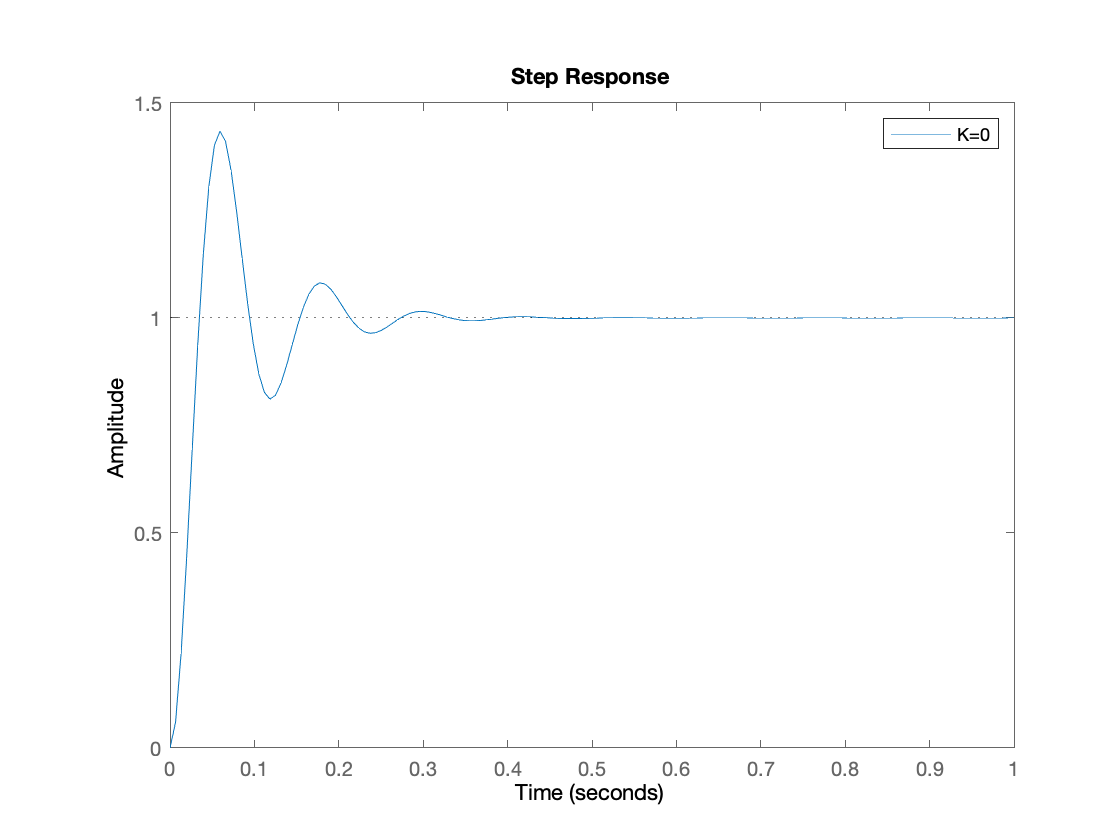

    step(Gmf,1)
end


legend('K=0', 'K=1')

## Análise do ganho utilizando lugar das raízes


% Função do tipo handle

F = function_handle with value:
    @(K,s)K*2979/(s^2+28*s+2979)



F =  @(K,s)  K*2979/(s^2+28*s+2979)

ans = 0.9906 - 0.0099i


F(1,1+j)  % notação é bem amigável

MalhaFechada = function_handle with value:
    @(Gma)Gma/(Gma+1)



MalhaFechada = @(Gma)  Gma/(Gma+1)

ans =
 
         2979 s^2 + 83412 s
  ---------------------------------
  s^4 + 56 s^3 + 3763 s^2 + 83412 s
 
Continuous-time transfer function.




MalhaFechada(Gma)



## Resposta Temporal

Filtro passa baixas 


$$H(s) = \frac{1}{sRC+1}$$


Frequência de corte


$$\omega_c = \frac{1}{RC}$$
